# TE: Validation of Optimal Price Design

**Description**: Code to produce numerical example in Section VI of [1].

**Outputs**: Figures to './fig'

**Assumptions and limitations**: none

**Other m-files required**: Files in './utils' and './functions'.

**MAT-files required**: Data in ''./data' and './output/SiouxFalls'

**Toolboxes required**: Included in './lib' Adaptive Robust Numerical Differentiation [2],  K-Shortest Path- Yen's algorithm [3].

**Authors**: Leonardo Pedroso, Andrea Agazzi, W.P.M.H. (Maurice) Heemels, Mauro Salazar

**Revision history**:

- 18/03/2026 - First draft of full implementation (Leonardo Pedroso)

**References**:

[1] L. Pedroso, A. Agazzi, W. P. M. H. Heemels, and M. Salazar, “Token Economy for Fair and Efficient Dynamic Resource Allocation in Congestion Games,” 2026, (submitted).

[2] John D'Errico (2026). Adaptive Robust Numerical Differentiation (https://nl.mathworks.com/matlabcentral/fileexchange/13490-adaptive-robust-numerical-differentiation), MATLAB Central File Exchange.

[3] Meral Sh. (2026). K-Shortest Path- Yen's algorithm (https://nl.mathworks.com/matlabcentral/fileexchange/32513-k-shortest-path-yen-s-algorithm), MATLAB Central File Exchange.

## Initialization

% Check if setup has been carried out
if ~exist('flag_setup_OK', 'var') || ~flag_setup_OK
    error("Setup of network congestion game has not been carried out.");
end

% Seed list (-1 for random seed)
rng_seed = 0;

% Random number seed:
if rng_seed < 0
    rng("shuffle");
    rng_seed = round(1e5*rand());
end

rng(rng_seed);
if verbose
    rng_seed
end

rng_seed = 0

## Compute optimal prices

flag_no_token_economy = true;

% Parameters
p_max = 50;
p = cell(C,1);

if ~flag_no_token_economy
    for c = 1:C
        p{c} = p_design_c(sigma_a_star{c,1},l_a_star{c,1},Rd,Rn,p_max);
    end
else
    for c = 1:C
        p{c} = zeros(size(sigma_a_star{c,1}));
    end
end

if verbose
    % fprintf("sigma^*:\n");
    % disp(sigma_r_star')
    % fprintf("l^*:\n");
    % disp(l_r_star')
    % fprintf("p^*:\n");
    % disp(pR')
    for c = 1:C
        if sum(abs(p{c})) > 1
            fprintf(sprintf("p^* (c = %d)\n",c));
            disp(p{c}')
        end
    end
end


## Simulation of a finite population

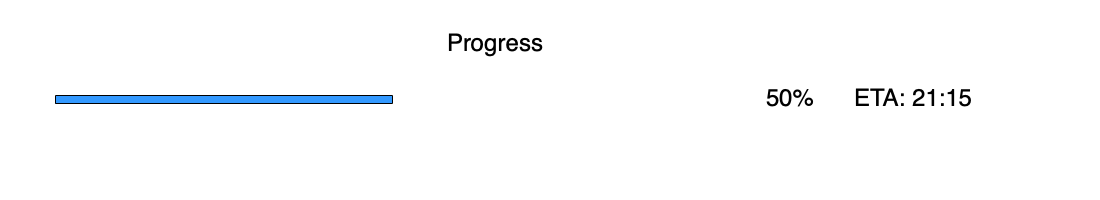

% Type of simulation
flag_approx_distributed = true;

% Simulation parameters
T_sim = 500;
dt_sim = 1;
t_span = 0:dt_sim:T_sim;
Ntraj = 1; % Number of trajectories to simulate
alpha_LP = 1-1e-4; % Low-pass filter pole
alpha_LP_dt = 1-0.05; % Low-pass filter pole

% Revision protocol parameters
% Type of revision protocol: Immitative (0), Pairwise cmp (1), Hybrid in (0,1) 
type_rev = 0.5;
Fu = payoff_handles(p,Ac,lr,k_max,Rd,Rn);
r_rpl = @(c,u,v,sigma) max(0,Fu{c}(v,sigma)-Fu{c}(u,sigma)); % Imitative via comparison
phi_cmp = @(c,u,v,sigma) max(0,Fu{c}(v,sigma)-Fu{c}(u,sigma)); % Smith

% Population evolution sampling
sigma_dt = cell(Ntraj,1);
sigma_a_dt = cell(Ntraj,1);
k_dt = cell(Ntraj,1);

% Price update evolution variables
sigma_dt_LP = cell(Ntraj,1);

% Trajectory computation
% parfor if necesssary
for traj = 1:Ntraj
    % Init sampling evolutions
    sigma_dt{traj} = zeros(R,length(t_span),C);
    sigma_a_dt{traj} = zeros(sum(A),length(t_span));
    k_dt{traj} = zeros(4,length(t_span),C);
    
    % Init price update evolutions
    sigma_dt_LP{traj} = zeros(R,length(t_span));

    % Init individual evolution 
    c_t = zeros(N,1); % Class of each agent
    u_t = cell(N,1); % Current policy of each agent
    
    % Initial condition
    % Define classes
    aux = 0;
    for c = 1:C
        c_t(aux+1:aux+Nc(c)) = c;
        aux = aux+Nc(c);
    end

     % States
    if ~flag_approx_distributed
        k_t = randi(length(K),N,1)-1;
        k_t_avg_LP = mean(k_t);
    else
        k_t = cell(N,1);
        for i = 1:N
            k_t{i} = randi(length(K),1,1)-1;
        end
        k_t_avg_LP = mean(cell2mat(k_t));
    end

    % Random policies
    for j = 1:N
        u_t{j} = rand_valid_pol(p{c_t(j)},k_max);
    end
   
    % Update aggregate variables
    if ~flag_approx_distributed
        sigma_t = update_sigma(c_t,k_t,u_t,R,Ac,Rd); % Current distribution of each player
    else
        sigma_t = update_sigma(c_t,cell2mat(k_t),u_t,R,Ac,Rd); % Current distribution of each player
    end
    sigma_t_LP = sigma_t;

    % Initialize agent's clocks
    if ~flag_approx_distributed
        next_ring_d = exprnd(1/Rd,N,1);
        next_ring_n = exprnd(1/Rn,N,1);
        next_ring_r = exprnd(1/Rr,N,1); % Next revision ring of each player
    else
        next_ring_d = cell(N,1);
        next_ring_n = cell(N,1);
        next_ring_r = cell(N,1); % Next revision ring of each player
        for i = 1:N
            next_ring_d{i} = exprnd(1/Rd,1,1);
            next_ring_n{i} = exprnd(1/Rn,1,1);
            next_ring_r{i} = exprnd(1/Rr,1,1); % Next revision ring of each player
        end
    end
        
    % Progress bar
    tStart = tic;
    fig = figure('Color', 'w', 'Position', [100, 100, 550, 100]);
    ax = axes('Position', [0.05, 0.3, 0.8, 0.4]);
    hBar = barh(0, 0, 'FaceColor', [0.2 0.6 1], 'BarWidth', 0.2);
    xlim([0 1.3]);  % Extend range to avoid clipping text
    ylim([-1 1]);
    set(ax, 'XTick', [], 'YTick', [], 'XColor', 'none', 'YColor', 'none', 'Box', 'off');
    title('Progress', 'FontSize', 12, 'FontWeight', 'normal');
    txtPercent = text(1.05, 0, '0%', 'FontSize', 12, 'VerticalAlignment', 'middle');
    txtETA     = text(1.18, 0, 'ETA: --:--', 'FontSize', 12, 'VerticalAlignment', 'middle');

    
    % Simulate dt at a time
    for i = 1:length(t_span)
        %%%% ------------------------------------- SEQUENTIAL -------------------------------------
        if ~flag_approx_distributed
            %% Simulate events
            while true
                % Find next event
                [t_ring, type_ring, idx_ring] = find_next_ring(next_ring_d,next_ring_r,next_ring_n);
        
                % Sample if next event is after t_span(i)
                if t_ring >= t_span(i)
                    % Update sampled population states
                    sigma_dt{traj}(:,i,:) = update_sigma_class(c_t,k_t,u_t,R,Ac,Rd); % Current distribution of each player;
                    sigma_dt_LP{traj}(:,i) = sigma_t_LP;
    
                    % Ammount of tokens
                    for c = 1:C
                        k_dt{traj}(1,i,c) = mean(k_t(c_t==c));
                        k_dt{traj}(2,i,c) = min(k_t(c_t==c));
                        k_dt{traj}(3,i,c) = max(k_t(c_t==c));
                        k_dt{traj}(4,i,c) = sqrt(var(k_t(c_t==c)));
                    end
                    break;
                end
    
                % Perform next event
                switch type_ring
                    case 1 % Dynamic ring
                        % Jump in individual state
                        k_t(idx_ring) = min([k_max k_t(idx_ring)-p{c_t(idx_ring)}(implement_pol(u_t{idx_ring},k_t(idx_ring)))]);
                        % Compute next ring
                        next_ring_d(idx_ring) = next_ring_d(idx_ring) + exprnd(1/Rd);
                    case 2 % Revision ring
                        if rand() < type_rev % Pairwise cmp
                            % Choose a random policy
                            v = rand_valid_pol(p{c_t(idx_ring)},k_max);
                            if rand() < phi_cmp(c_t(idx_ring),u_t{idx_ring},v,sigma_t)/Rr % Immitate w/ prob. r_uv/R_r
                                u_t{idx_ring} = v;
                            end
                        else % Imitative
                            % Choose a random player of the population to compare
                            aux = find(c_t == c_t(idx_ring));
                            v = u_t{aux(randi(length(aux)))};
                            if rand() < r_rpl(c_t(idx_ring),u_t{idx_ring},v,sigma_t)/Rr % Immitate w/ prob. r_uv/R_r
                                u_t{idx_ring} = v;
                            end
                        end
                        % Compute next ring
                        next_ring_r(idx_ring) = next_ring_r(idx_ring) + exprnd(1/Rr);
                    case 3 % Noise ring
                        % Give gift of one token
                        k_t(idx_ring) = min([k_max k_t(idx_ring)+1]);
                        % Compute next ring
                        next_ring_n(idx_ring) = next_ring_n(idx_ring) + exprnd(1/Rn);
                end
                % Update aggregate variables
                % (Instead of sampling we could also get the exact trajectory here)
                sigma_t = update_sigma(c_t,k_t,u_t,R,Ac,Rd); % Current distribution of each player
                sigma_t_LP = alpha_LP*sigma_t_LP + (1-alpha_LP)*sigma_t;
                k_t_avg_LP = alpha_LP*k_t_avg_LP + (1-alpha_LP)*mean(k_t);
            end
        %%%% ------------------------------------- SEQUENTIAL -------------------------------------
        else
        %%%% ------------------------------------- PARALLEL -------------------------------------
            
            % Previous policies (for imitative dynamics) and sigma_t
            u_t_prev = u_t;
            sigma_t_prev = sigma_t; % sigma_dt_LP{traj}(:,i-1) % Consider using LP
    
            % Simulate events        
            parfor idx_ring = 1:N
            %for idx_ring = 1:N
                while true
                    % Find next event
                    [t_ring, type_ring] = min([next_ring_d{idx_ring},next_ring_r{idx_ring},next_ring_n{idx_ring}]);
    
                    % Break loop and sample if next event is after t_span(i)
                    if t_ring >= t_span(i)
                        break;
                    end
    
                    % Perform next event
                    switch type_ring
                        case 1 % Dynamic ring
                            % Jump in individual state
                            k_t{idx_ring} = min([k_max k_t{idx_ring}-p{c_t(idx_ring)}(implement_pol(u_t{idx_ring},k_t{idx_ring}))]);
                            % Compute next ring
                            next_ring_d{idx_ring} = next_ring_d{idx_ring} + exprnd(1/Rd);
                        case 2 % Revision ring
                            if rand() < type_rev % Pairwise cmp
                                % Choose a random policy
                                v = rand_valid_pol(p{c_t(idx_ring)},k_max);
                                %fprintf(fileID, '%g\n',phi_cmp(c_t(idx_ring),u_t{idx_ring},v,sigma_t_prev)/Rr);
                                if rand() < phi_cmp(c_t(idx_ring),u_t{idx_ring},v,sigma_t_prev)/Rr % Immitate w/ prob. r_uv/R_r
                                    u_t{idx_ring} = v;
                                end
                            else % Imitative
                                % Choose a random player of the population to compare
                                aux = find(c_t == c_t(idx_ring));
                                v = u_t_prev{aux(randi(length(aux)))};
                                %fprintf(fileID, '%g\n',r_rpl(c_t(idx_ring),u_t{idx_ring},v,sigma_t_prev)/Rr);
                                if rand() < r_rpl(c_t(idx_ring),u_t{idx_ring},v,sigma_t_prev)/Rr % Immitate w/ prob. r_uv/R_r
                                    u_t{idx_ring} = v;
                                end
                            end
                            % Compute next ring
                            next_ring_r{idx_ring} = next_ring_r{idx_ring} + exprnd(1/Rr);
                        case 3 % Noise ring
                            % Give gift of one token
                            k_t{idx_ring} = min([k_max k_t{idx_ring}+1]);
                            % Compute next ring
                            next_ring_n{idx_ring} = next_ring_n{idx_ring} + exprnd(1/Rn);
                    end
                end
            end
    
            % Update sampled population states
            sigma_dt{traj}(:,i,:) = update_sigma_class(c_t,cell2mat(k_t),u_t,R,Ac,Rd); % Current distribution of each player;
            sigma_a_dt{traj}(:,i) = update_sigma_a(c_t,cell2mat(k_t),u_t,Ac,Rd);
            sigma_t = update_sigma(c_t,cell2mat(k_t),u_t,R,Ac,Rd);
            if i >  1
                sigma_dt_LP{traj}(:,i) = sigma_dt_LP{traj}(:,i-1)*alpha_LP_dt + (1-alpha_LP_dt)*sigma_t;
            else
                sigma_dt_LP{traj}(:,i) = sigma_t;
            end    
            % Ammount of tokens
            for c = 1:C
                k_t_aux = cell2mat(k_t);
                k_dt{traj}(1,i,c) = mean(k_t_aux(c_t==c));
                k_dt{traj}(2,i,c) = min(k_t_aux(c_t==c));
                k_dt{traj}(3,i,c) = max(k_t_aux(c_t==c));
                k_dt{traj}(4,i,c) = sqrt(var(k_t_aux(c_t==c)));
            end
        %%%% ------------------------------------- PARALLEL -------------------------------------
        end
        % Progress bar update
        frac = i / length(t_span); 
        hBar.YData = frac;
        txtPercent.String = sprintf('%d%%', round(frac * 100));
        elapsed = toc(tStart);
        if frac > 0
            totalEstimated = elapsed / frac;
            remaining = totalEstimated - elapsed;
            txtETA.String = sprintf('ETA: %02d:%02d', floor(remaining/60), mod(round(remaining), 60));
        end
        drawnow;
    end
end

toc


## Post-processing

% Analyse Payoffs
F_t = zeros(C,3);
for c = 1:C
    Cc = find(c_t == c);
    aux = zeros(length(Cc),1);
    count = 1;
    for j = Cc'
        aux(count) = Fu{c}(u_t{j},sigma_t);
        count = count+1;
    end
    F_t(c,:) = [min(aux) mean(aux) max(aux)];
end
F_t

% Evolution of cost
J_eff_F = cell(Ntraj,1);
for traj = 1:Ntraj
    J_eff_F{traj} = zeros(1,length(t_span));
    for i = 1:length(t_span)
        J_eff_F{traj}(i) = J(sigma_a_dt{traj}(:,i));
    end
end

% W bar
% sigma_a2w_bar(sigma_a,C,R,A,Ac,lr)
w_bar_dt = cell(Ntraj,1);
for traj = 1:Ntraj
    w_bar_dt{traj} = zeros(C,length(t_span));
    for i = 1:length(t_span)
        w_bar_dt{traj}(:,i) = sigma_a2w_bar(sigma_a_dt{traj}(:,i),C,R,A,Ac,lr);
    end
end


## Plots

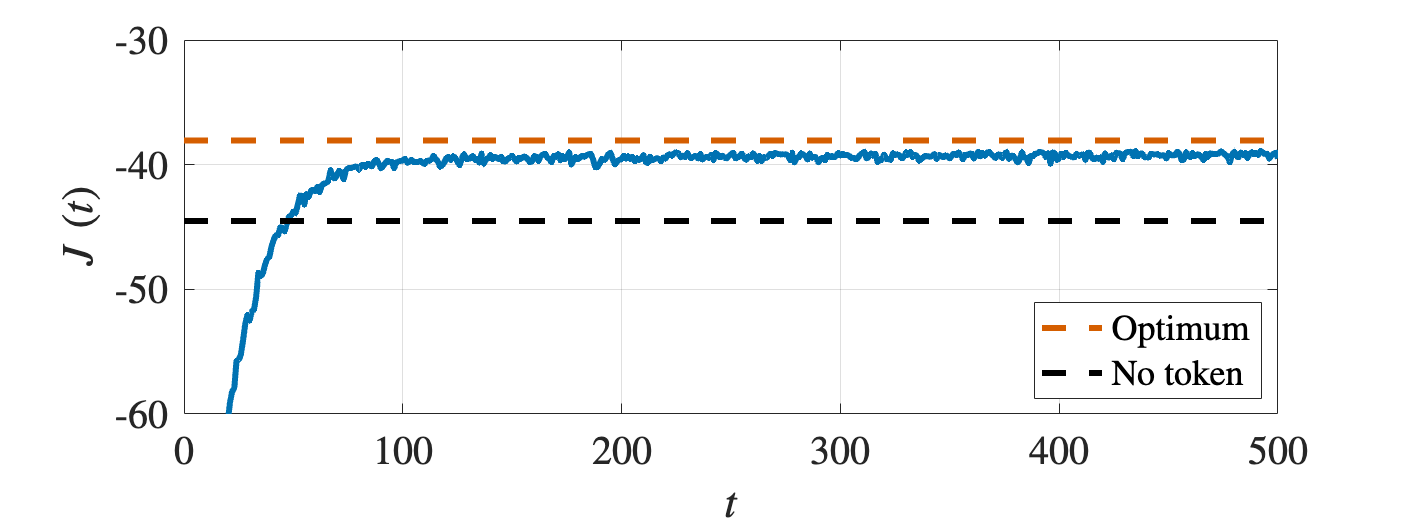

% Plot cost
load('J_no_token.mat','J_no_token');
traj = 1;
figure('Position',4*[0 0 192 144/2]); % Nice aspect ratio for double column
hold on;
grid on;
box on;
set(gca,'FontSize',20);
set(gca,'TickLabelInterpreter','latex') % Latex style axis 
plot(t_span,-J_eff_F{traj},'LineWidth',3,'Color',color.blue,'HandleVisibility','off');
plot([t_span(1) t_span(end)], -J(cell2mat(sigma_a_star))*[1 1],'--','LineWidth',3,'Color',color.red);
plot([t_span(1) t_span(end)], -J_no_token*[1 1],'--','LineWidth',3,'Color',color.black);
legend({'Optimum','No token'},'Interpreter','latex','Location','southeast');
% Labels
xlabel("$t$",'Interpreter','latex');
ylabel("$J\;(t)$",'Interpreter','latex');
ylim([-60 -30]);
exportgraphics(gcf,'./fig/J.pdf','ContentType', 'vector');

J_token = mean(J_eff_F{traj}(end-200:end));
100*(J_no_token-J_token)/J_token

ans = 13.3407

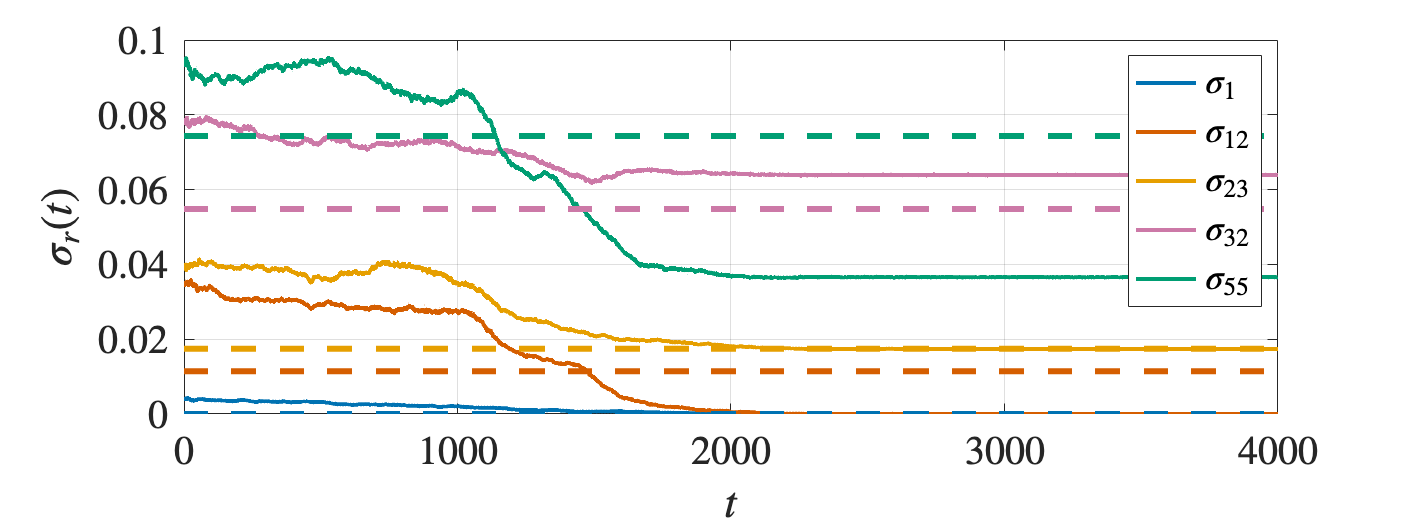

% Plot resource flows
traj = 1;
figure('Position',4*[0 0 192 144/2]); % Nice aspect ratio for double column
hold on;
grid on;
box on;
set(gca,'FontSize',20);
set(gca,'TickLabelInterpreter','latex') % Latex style axis 
% Trajectories 
%rng(5);
rng(1)
R_plot = sort(randi([1 R],5));
R_color = [color.blue; color.red; color.orange; color.pink; color.green];
% Sigma evolution
for j = 1:length(R_plot)
    plot(t_span,sum(sigma_dt{traj}(R_plot(j),:,:),3),'LineWidth',2,'Color',R_color(j,:));
end
% Optimal flows
for j = 1:length(R_plot)
    p = plot([t_span(1) t_span(end)],[sigma_r_star(R_plot(j)) sigma_r_star(R_plot(j))],'--','LineWidth',3,'Color',R_color(j,:)); 
end
% Labels
xlabel("$t$",'Interpreter','latex');
ylabel("$\sigma_r(t)$",'Interpreter','latex');
legend({sprintf("$\\sigma_{%d}$",R_plot(1)),sprintf("$\\sigma_{%d}$",R_plot(2)),sprintf("$\\sigma_{%d}$",R_plot(3)),sprintf("$\\sigma_{%d}$",R_plot(4)),sprintf("$\\sigma_{%d}$",R_plot(5))},'Interpreter','latex');
exportgraphics(gcf,'./fig/sigma.pdf','ContentType', 'vector');

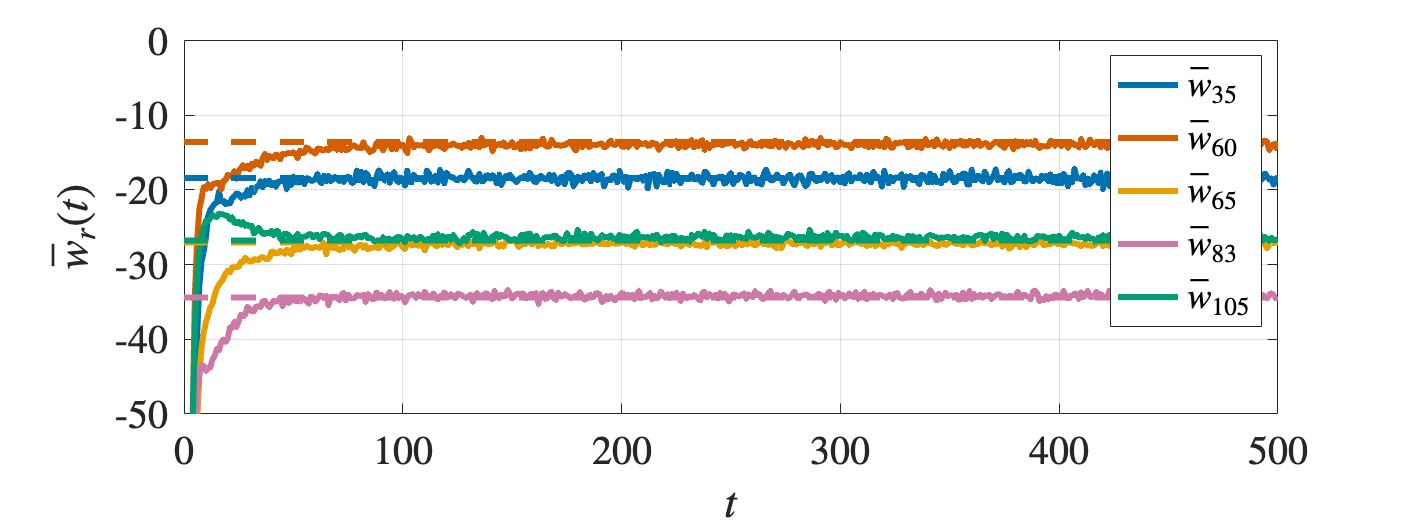

% Plot w_bar
traj = 1;
figure('Position',4*[0 0 192 144/2]); % Nice aspect ratio for double column
hold on;
grid on;
box on;
set(gca,'FontSize',20);
set(gca,'TickLabelInterpreter','latex') % Latex style axis 
% Trajectories 
%rng(5);
rng(3)
C_plot = sort(randi([1 C],5));
R_color = [color.blue; color.red; color.orange; color.pink; color.green];
% Sigma evolution
for j = 1:length(C_plot)
    plot(t_span,w_bar_dt{traj}(C_plot(j),:),'LineWidth',3,'Color',R_color(j,:));
end
% Optimal flows
for j = 1:length(C_plot)
    p = plot([t_span(1) t_span(end)],[w_bar_star(C_plot(j)) w_bar_star(C_plot(j))],'--','LineWidth',3,'Color',R_color(j,:)); 
end
% Labels
xlabel("$t$",'Interpreter','latex');
ylabel("$\bar{w}_r(t)$",'Interpreter','latex');
ylim([-50 0.07]);
legend({sprintf("$\\bar{w}_{%d}$",C_plot(1)),sprintf("$\\bar{w}_{%d}$",C_plot(2)),sprintf("$\\bar{w}_{%d}$",C_plot(3)),sprintf("$\\bar{w}_{%d}$",C_plot(4)),sprintf("$\\bar{w}_{%d}$",C_plot(5))},'Interpreter','latex');
% % Save figure
exportgraphics(gcf,'./fig/w_bar.pdf','ContentType', 'vector');

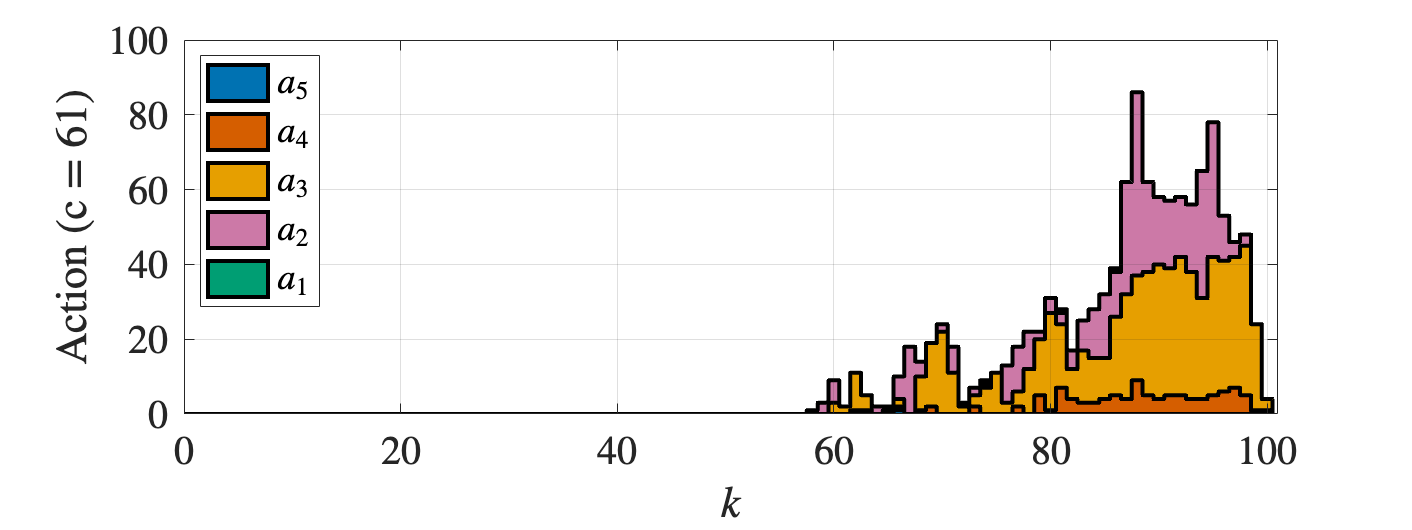

% This map only weighs levels where agents actually are
a_end = cell(C,1);
for c = 1:C
    % Extra token level k_max +1 just for plotting
    a_end{c} = zeros(A(c),k_max+2);
    % Agents in class c
    Cc = find(c_t == c);
    aux = zeros(length(Cc),1);
    count = 1;
        for j = Cc'
            if ~flag_approx_distributed
                a_end{c}(implement_pol(u_t{j},k_t(j)),k_t(j)+1) = a_end{c}(implement_pol(u_t{j},k_t(j)),k_t(j)+1) + 1;
            else
                a_end{c}(implement_pol(u_t{j},k_t{j}),k_t{j}+1) = a_end{c}(implement_pol(u_t{j},k_t{j}),k_t{j}+1) + 1;
            end
            
        end
end
R_color = [color.blue; color.red; color.orange; color.pink; color.green; color.black; color.black; color.black; color.black; color.black];
rng(14);
c = randi(C);
%c = 52;
c = 61;
figure('Position',4*[0 0 192 144/2]);
hold on;
grid on;
box on;
set(gca,'FontSize',20);
set(gca, 'Layer', 'top');
set(gca,'TickLabelInterpreter','latex');
for j = A(c):-1:1
    aux_x = (0:k_max+1)';
    aux_y = sum(a_end{c}(1:j,1:end),1)';
    [aux_x,aux_y] = stairs_vector(aux_x,aux_y);
    a = area(aux_x-0.5,aux_y,'LineWidth',2,'FaceColor',R_color(j,:));
    if j > 5
        a.HandleVisibility = 'off';
    end
end
xlim([0, k_max+1]);
xlabel('$k$','Interpreter','latex');
ylabel(sprintf('Action (c = %d)',c),'Interpreter','latex');
legend({'$a_1$','$a_2$','$a_3$','$a_4$','$a_5$'},'Interpreter','latex','Location','northwest');
hold off;
exportgraphics(gcf,'./fig/actions.pdf','ContentType', 'vector');

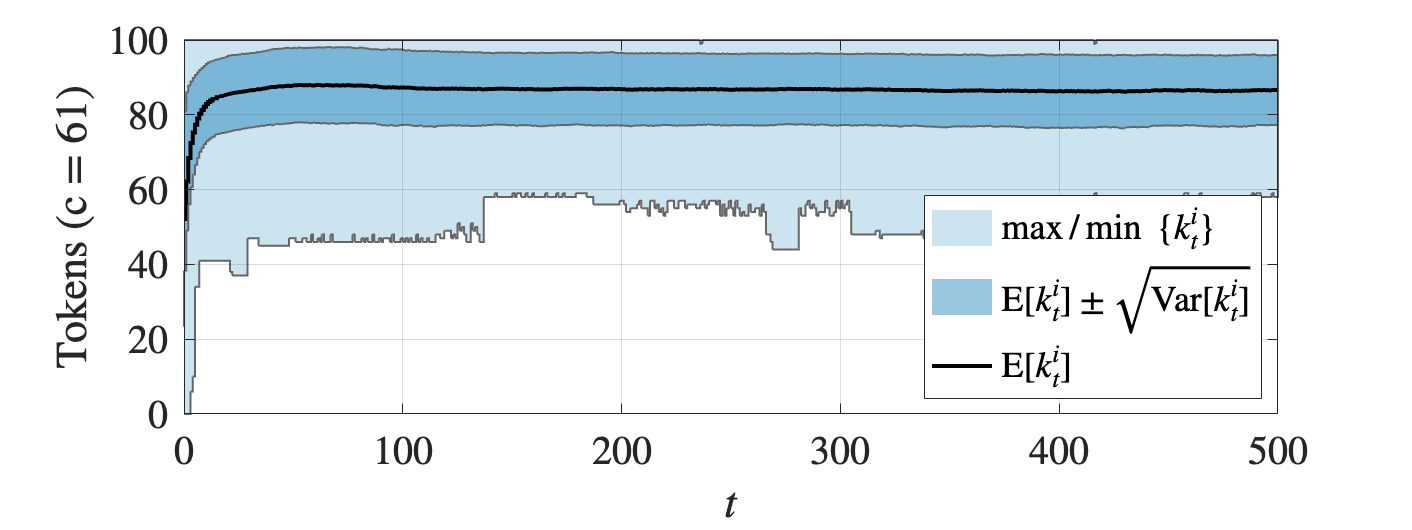

% AC level
traj = 1;
% c = 44;
% c = 71;
k_dt_mean = k_dt{traj}(1,:,c);
k_dt_min = k_dt{traj}(2,:,c);
k_dt_max = k_dt{traj}(3,:,c);
k_dt_var = k_dt{traj}(4,:,c);
t_span_len = length(t_span)-1;
figure('Position',4*[0 0 192 144/2]);
hold on;
grid on;
box on;
set(gca,'FontSize',20);
set(gca, 'Layer', 'top');
set(gca,'TickLabelInterpreter','latex');
aux_x2 = [t_span fliplr(t_span)]';
aux_y2 = [k_dt_max fliplr(k_dt_min)]';
[aux_x2,aux_y2] = stairs_vector(aux_x2,aux_y2);
fill(aux_x2,aux_y2,'k',...
    'LineWidth',2,'FaceColor',color.blue,'FaceAlpha',0.2,'EdgeAlpha',0);
aux_x1 = [t_span fliplr(t_span)]';
aux_y1 = [k_dt_mean+k_dt_var fliplr(k_dt_mean-k_dt_var)]';
aux_y1(aux_y1<0) = 0;
[aux_x1,aux_y1] = stairs_vector(aux_x1,aux_y1);
fill(aux_x1,aux_y1,'k',...
    'LineWidth',2,'FaceColor',color.blue,'FaceAlpha',0.4,'EdgeAlpha',0);
stairs(t_span,k_dt_mean,'LineWidth',2,'Color','black');
stairs(aux_x1,aux_y1,'LineWidth',1,'Color',[0.4 0.4 0.4]);
stairs(aux_x2,aux_y2,'LineWidth',1,'Color',[0.4 0.4 0.4]);
legend({' $\max$/$\min$ $\{k^i_t\}$',' $\mathrm{E}[k^i_t]\pm\sqrt{\mathrm{Var}[k^i_t]}$',' $\mathrm{E}[k^i_t]$'},...
    'Location','southeast','Interpreter','latex');
ylabel(sprintf('Tokens (c = %d)',c),'Interpreter','latex');
xlabel('$t$','Interpreter','latex');
% xlim ([0 100]);
ylim ([0 k_max]);
% Save figure to .fig and .png formats
hold off;
exportgraphics(gcf,'./fig/tokens.pdf','ContentType', 'vector');

% Plot resource flows
traj = 1;
figure('Position',4*[0 0 192 144]); % Nice aspect ratio for double column
hold on;
grid on;
box on;
set(gca,'FontSize',20);
set(gca,'TickLabelInterpreter','latex') % Latex style axis 
% Trajectories 
R_plot = [1 2 3 6 7];
R_color = [color.blue; color.red; color.orange; color.pink; color.green];
for j = 1:length(R_plot)
    plot(t_span,sigma_dt_LP{traj}(R_plot(j),:),'LineWidth',2,'Color',R_color(j,:));
end
for j = 1:length(R_plot)
    p = plot([t_span(1) t_span(end)],[sigma_r_star(R_plot(j)) sigma_r_star(R_plot(j))],'--','LineWidth',2,'Color',R_color(j,:)); 
end
% Labels
xlabel("$t$",'Interpreter','latex');
ylabel("$\hat{\sigma}^{\mathrm{LP}}_r(t)$",'Interpreter','latex');
legend({"$\hat{\sigma}_1$","$\hat{\sigma}_2 = \hat{\sigma}_4$","$\hat{\sigma}_3$","$\hat{\sigma}_5 = \hat{\sigma}_6$","$\hat{\sigma}_7$"},'Interpreter','latex');

% Plot cost
traj = 1;
figure('Position',4*[0 0 192 144]); % Nice aspect ratio for double column
hold on;
grid on;
box on;
set(gca,'FontSize',20);
set(gca,'TickLabelInterpreter','latex') % Latex style axis 
plot(t_span,J_eff{traj},'LineWidth',2,'Color',color.blue);
plot([t_span(1) t_span(end)], J_eff_sigma_r(sigma_r_star)*[1 1],'--','LineWidth',2,'Color',color.red);
% Labels
xlabel("$t$",'Interpreter','latex');
ylabel("$J_{\mathrm{eff}}\;(t)$",'Interpreter','latex');

% AC level
traj = 1;
for c = 1:C
    k_dt_mean = k_dt{traj}(1,:,c);
    k_dt_min = k_dt{traj}(2,:,c);
    k_dt_max = k_dt{traj}(3,:,c);
    k_dt_var = k_dt{traj}(4,:,c);
    t_span_len = length(t_span)-1;
    figure('Position',4*[0 0 192 144/2]);
    hold on;
    grid on;
    box on;
    set(gca,'FontSize',20);
    set(gca, 'Layer', 'top');
    set(gca,'TickLabelInterpreter','latex');
    aux_x2 = [t_span fliplr(t_span)]';
    aux_y2 = [k_dt_max fliplr(k_dt_min)]';
    [aux_x2,aux_y2] = stairs_vector(aux_x2,aux_y2);
    fill(aux_x2,aux_y2,'k',...
        'LineWidth',2,'FaceColor',color.blue,'FaceAlpha',0.2,'EdgeAlpha',0);
    aux_x1 = [t_span fliplr(t_span)]';
    aux_y1 = [k_dt_mean+k_dt_var fliplr(k_dt_mean-k_dt_var)]';
    aux_y1(aux_y1<0) = 0;
    [aux_x1,aux_y1] = stairs_vector(aux_x1,aux_y1);
    fill(aux_x1,aux_y1,'k',...
        'LineWidth',2,'FaceColor',color.blue,'FaceAlpha',0.4,'EdgeAlpha',0);
    stairs(t_span,k_dt_mean,'LineWidth',2,'Color','black');
    stairs(aux_x1,aux_y1,'LineWidth',1,'Color',[0.4 0.4 0.4]);
    stairs(aux_x2,aux_y2,'LineWidth',1,'Color',[0.4 0.4 0.4]);
    legend({' $\max$/$\min$ $\{K_t\}$',' $\mathrm{E}[K_t]\pm\sqrt{\mathrm{Var}[K_t]}$',' $\mathrm{E}[K_t]$'},...
        'Location','northeast','Interpreter','latex');
    ylabel(sprintf('Tokens (c = %d)',c),'Interpreter','latex');
    xlabel('$t$','Interpreter','latex');
    % xlim ([0 100]);
    ylim ([0 k_max]);
    hold off;
end

% This map only weighs levels where agents actually are
a_end = cell(C,1);
for c = 1:C
    % Extra token level k_max +1 just for plotting
    a_end{c} = zeros(A(c),k_max+2);
    % Agents in class c
    Cc = find(c_t == c);
    aux = zeros(length(Cc),1);
    count = 1;
        for j = Cc'
            if ~flag_approx_distributed
                a_end{c}(implement_pol(u_t{j},k_t(j)),k_t(j)+1) = a_end{c}(implement_pol(u_t{j},k_t(j)),k_t(j)+1) + 1;
            else
                a_end{c}(implement_pol(u_t{j},k_t{j}),k_t{j}+1) = a_end{c}(implement_pol(u_t{j},k_t{j}),k_t{j}+1) + 1;
            end
            
        end
end
R_color = [color.blue; color.red; color.orange; color.pink; color.green];
for c = 1:C
    figure('Position',4*[0 0 192 144/2]);
    hold on;
    grid on;
    box on;
    set(gca,'FontSize',20);
    set(gca, 'Layer', 'top');
    set(gca,'TickLabelInterpreter','latex');
    for j = A(c):-1:1
        aux_x = (0:k_max+1)';
        aux_y = sum(a_end{c}(1:j,1:end),1)';
        [aux_x,aux_y] = stairs_vector(aux_x,aux_y);
        a = area(aux_x,aux_y,'LineWidth',2,'FaceColor',R_color(j,:));
    end
    xlim([0, k_max+1]);
    xlabel('$k$','Interpreter','latex');
    ylabel(sprintf('Action (c = %d)',c),'Interpreter','latex');
    legend({'$a_1$','$a_2$','$a_3$','$a_4$'},'Interpreter','latex','Location','best');
    hold off;
end